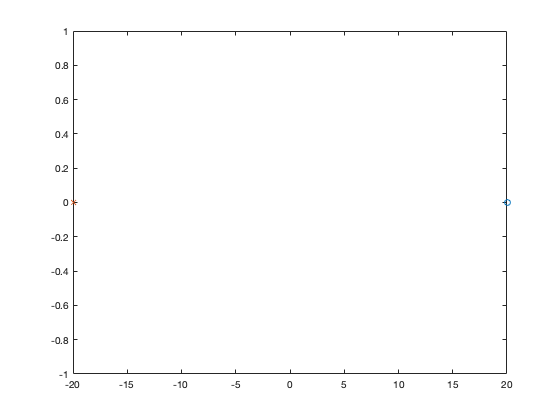

% n=1
s = tf('s');
sys = exp(-0.1*s);
sysx1 = pade(sys,1);
% n=2
s = tf('s');
sys = exp(-0.1*s);
sysx2 = pade(sys,2);
% n=4
s = tf('s');
sys = exp(-0.1*s);
sysx3 = pade(sys,4);
% n=8
s = tf('s');
sys = exp(-0.1*s);
sysx4 = pade(sys,8);
%find zeros and poles
zero1 = zero(sysx1);
pole1 = pole(sysx1);
zero2 = zero(sysx2);
pole2 = pole(sysx2);
zero3 = zero(sysx3);
pole3 = pole(sysx3);
zero4 = zero(sysx4);
pole4 = pole(sysx4);
 
real_zero1 = real(zero1);
image_zero1 = imag(zero1);
 
real_zero2 = real(zero2);
image_zero2 = imag(zero2);
 
real_zero3 = real(zero3);
image_zero3 = imag(zero3);
 
real_zero4 = real(zero4);
image_zero4 = imag(zero4);
 
real_pole1 = real(pole1);
image_pole1 = imag(pole1);
 
real_pole2 = real(pole2);
image_pole2 = imag(pole2);
 
real_pole3 = real(pole3);
image_pole3 = imag(pole3);
 
real_pole4 = real(pole4);
image_pole4 = imag(pole4);
%plot
plot(real_zero1,image_zero1,'o',real_pole1,image_pole1,'x')

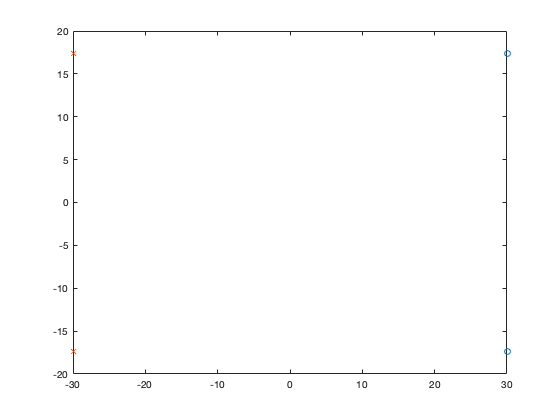

plot(real_zero2,image_zero2,'o',real_pole2,image_pole2,'x')

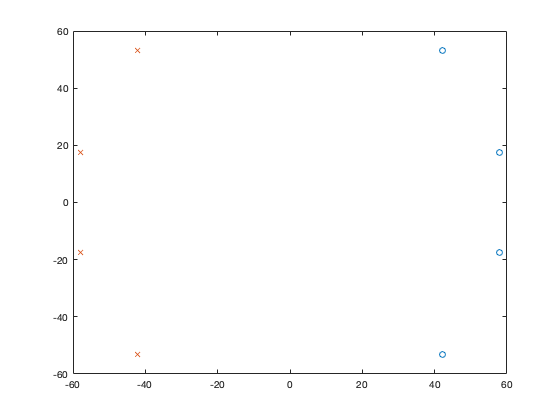

plot(real_zero3,image_zero3,'o',real_pole3,image_pole3,'x')

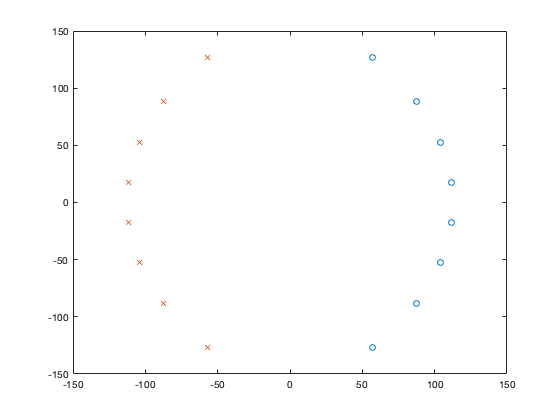

plot(real_zero4,image_zero4,'o',real_pole4,image_pole4,'x')

%Discuss: 
% A Pade approximation allows us to get the closest approximation of a function near a specific point. 
% As the nth order gets larger, we see that we have more zeros and poles plotted as we get better and better approximations.